# Exploring the 2-point correlation function in TNG-clusters


global LBox
global illUnits


loadFofSub;

mv=fofs.Group_M_Crit200.*illUnits.massUnit;


% define the radial profile 
rmin=1000./illUnits.lengthUnit; % 1Mpc in simulation units (kind off) 
rmax=0.87*LBox;  % slightly more than sqrt(3)/2 of boxsize - maximal relevant radius 



msk=log10(mv)>=13;
    
pos=fofs.GroupPos(:,msk);

figure
   

rprof1=logspace(log10(rmin),log10(rmax),100);
cf2p1=illustris.analysis.twopoint_correlation(pos,rprof1,LBox);

rprof2=linspace(rmin,rmax,100);
cf2p2=illustris.analysis.twopoint_correlation(pos,rprof2,LBox);

loglog(rprof1(1:end-1).*illUnits.lengthUnit./1000,cf2p1-1)
hold on 
loglog(rprof2(1:end-1).*illUnits.lengthUnit./1000,cf2p2-1)
loglog(0.5*LBox.*illUnits.lengthUnit.*[1 1]/1000,[1 1000],':k')
legend('log','lin')
myAxis();
xlabelmine('radius [Mpc]');

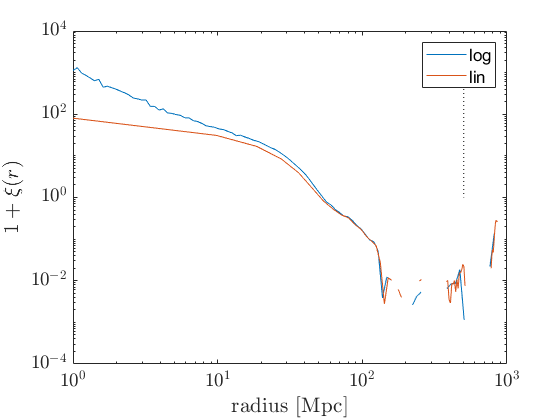

ylabelmine('$1+\xi(r)$');

## Exploring 2pcf at different mass bins

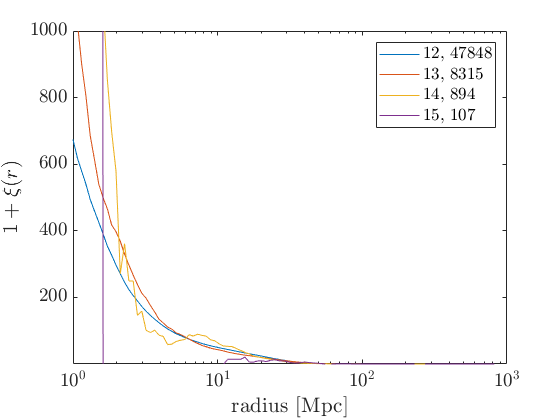

%massBins=[13 13.5 14 14.5 15 15.5];
massBins=[12 13 14  15 16];
%rprof=linspace(rmin,rmax,100);
rprof=logspace(log10(rmin),log10(rmax),100);
figure;
h=[];
for i=1:length(massBins)-1
    
    msk=log10(mv)>=massBins(i) & log10(mv)<massBins(i+1);
    
    pos=fofs.GroupPos(:,msk);
    
    cf2p=illustris.analysis.twopoint_correlation(pos,rprof,LBox);
    
    h(i)=semilogx(rprof(1:end-1).*illUnits.lengthUnit./1000,smooth(cf2p)-1,'DisplayName',[num2str(massBins(i)) ', ' num2str(sum(msk))]);
    if i==1; hold on; end
end
 msk=log10(mv)>=massBins(1);

legend(h,'Interpreter','latex')
ylim([0.001 1000])
myAxis();
xlabelmine('radius [Mpc]');
ylabelmine('$1+\xi(r)$');

## Playing around with different options

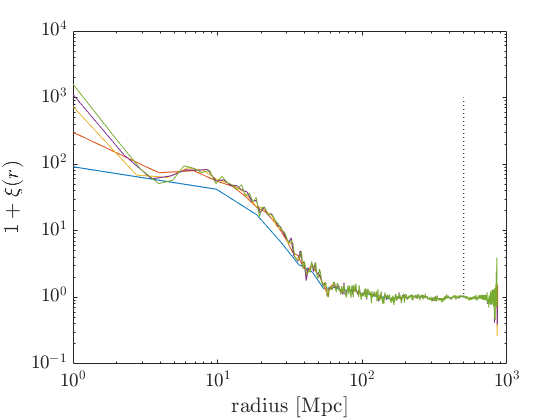




figure

for i=1:2:10 
    

rprof=linspace(rmin,rmax,100*i);
cf2p=illustris.analysis.twopoint_correlation(pos,rprof,LBox);

loglog(rprof(1:end-1).*illUnits.lengthUnit./1000,cf2p)
if i==1
    hold on
end
end

loglog(0.5*LBox.*illUnits.lengthUnit.*[1 1]/1000,[1 1000],':k')

myAxis();
xlabelmine('radius [Mpc]');
ylabelmine('$1+\xi(r)$');

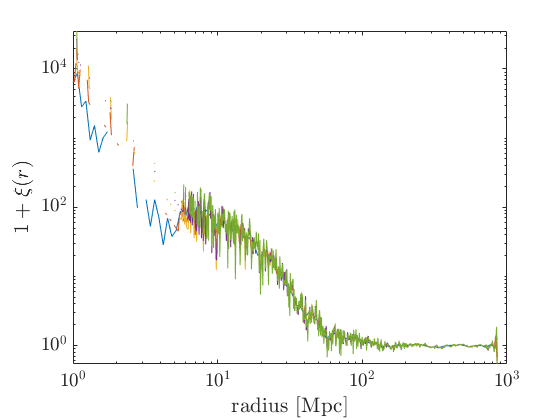

figure

for i=1:2:10 
    

rprof=logspace(log10(rmin),log10(rmax),100*i);
cf2p=illustris.analysis.twopoint_correlation(pos,rprof,LBox);

loglog(rprof(1:end-1).*illUnits.lengthUnit./1000,cf2p)
if i==1
    hold on
end
end

myAxis();
xlabelmine('radius [Mpc]');
ylabelmine('$1+\xi(r)$');

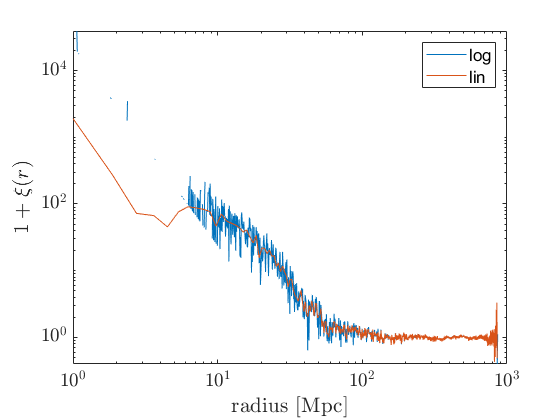

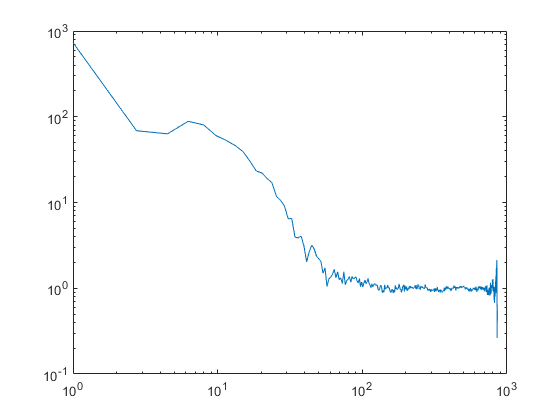

figure
loglog(rprof(1:end-1).*illUnits.lengthUnit./1000,cf2p)